close all
clear all
clc
plot_counter=1;
Question_mark='Q31';

run('BASIC.m')
d=16

d = 16

n=length(A)-1;

[alpha,beta]=d_step_maker(A,B,d);

T_s=0.1;
tfinal=100;
freq=15;
variance=0.01;
C=0;
[uc,t,Status,tfinal,Noix]=Datagen(1,T_s,tfinal,freq,variance,C);
Titlework=[Question_mark,Status];
% uc(1:40,1)=ones(40,1);

Delay identification

y=zeros(1,numel(t));

dg=d+length(B);
u=uc';
theta_hat=zeros((n+dg),numel(t));
theta_hat=ones((n+dg),40);
p_per=10^8*eye(n+dg);

for i=d+n+1:1:numel(t)-d
%     if i==floor(Ns/3)
%         A=poly([.1,.7]);
%         B=poly(.7);
%     end
    y(i)=-A(2:end)*y(i-1:-1:i-n)'+B*u(i-d0:-1:i-d0-length(B)+1)';
    phi=[-y(i-1:-1:i-n),u(i:-1:i-d-length(B)+1)]';
    k=(p_per*phi)*(((1+phi'*p_per*phi))^-1);
    theta_hat(:,i)=theta_hat(:,i-1)+k*(y(i)-phi'*theta_hat(:,i-1));
    p=(eye(n+dg)-k*phi')*p_per;
    p_per=p;
end

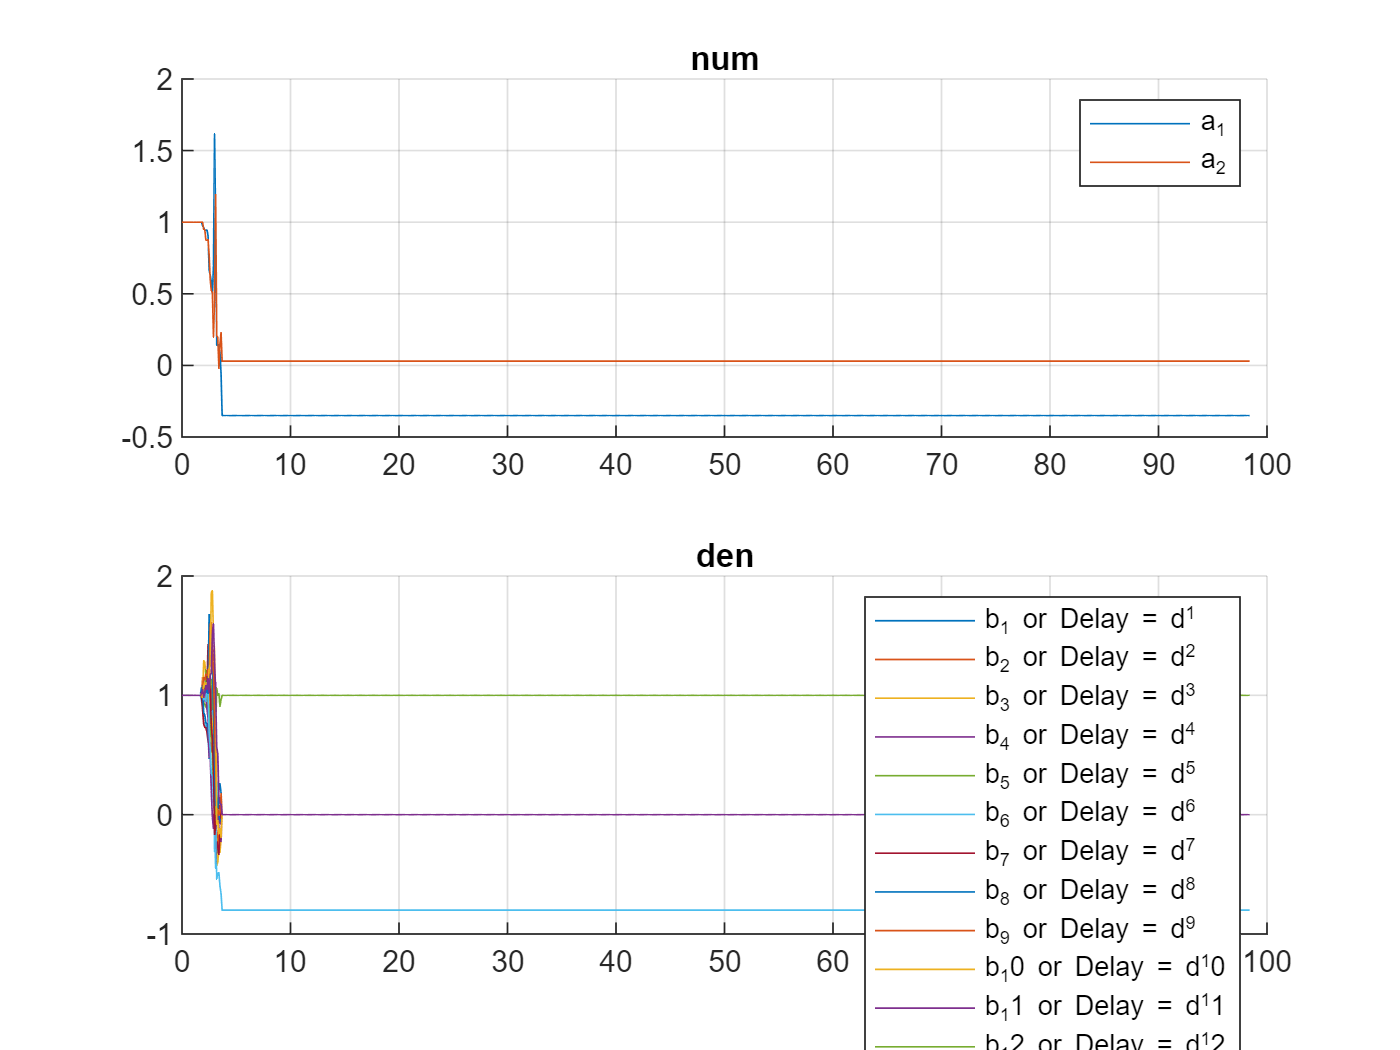

clear i
figure(1)
subplot(2,1,1)
    V1= "a_" + (1:1:2);
    hold on
    for i=1:n
        plot(t(1:end-d),theta_hat(i,:))
    end
    legend(V1)
    title('num')
    grid on

subplot(2,1,2)
    V2="b_" + (1:1:dg) + " or Delay = d^" + (1:1:dg);
    hold on
    clear i
    for i=n+1:dg+n
        plot(t(1:end-d),theta_hat(i,:))
    end
    legend(V2)
    title('den')
    grid on

% print(gcf,[Titlework , '.png'],'-dpng','-r400');    